# Matching Pursuit (MP)

Implementing the Matching Pursuit (MP) algorithm which was proposed by [1] with an example from[2].

Dictionary, $D$ is set of $n$ vectors in dimention $d$ which spans the vector space. Usually it is overcomplete, $d<n$.


$$x_i  \in \mathbb{R}^d\\ 
D = \{x_1 ,x_2,\dots,x_n\}\in \mathbb{R}^{d,n}$$


The goal is to represent/approximate a random vector $f \in \mathbb{R}^d$ as linear combination of vectors isn the dictionary.

[1] S. Mallat and Z. Zhang. Matching pursuits with time-frequency dictionaries. Preprint. Submitted to IEEE Transactions on Signal Processing, 1992.

[2] Y. Pati, R. Rezaiifar, and P. Krishnaprasad, “Orthogonal matching pursuit: Recursive function approximation with applications to wavelet decomposition,” in Proceedings of 27th Asilomar Conference on Signals,Systems and Computers, pp. 40–44, IEEE, IEEE Comput. Soc. Press,1993

An example showcasing the sub-optimality of the MP algorithm as shown in [2].

x = [1  exp(pi*1i/8)]   % Dictionary elements in complex notation ||x|| =1 

x =    1.0000 + 0.0000i   0.9239 + 0.3827i



D = [real(x); imag(x)]  % Overcomplete dictionary [x-1 x_2 ... x_n]

D =     1.0000    0.9239
         0    0.3827



f = [real(exp(pi*1i/3)); imag(exp(pi*1i/3))] % The target vector

f =     0.5000
    0.8660


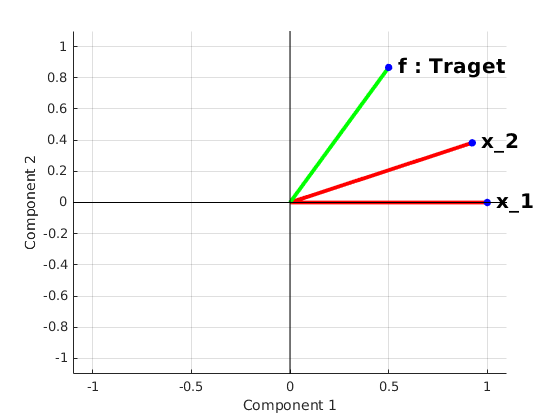


fig1 = figure();
h1 =biplot([D.';f'],'VarLabels',{' x_1',' x_2',' f : Traget'},"LineWidth",3,'MarkerSize',20);
hold on
for i =1:3
    h1(i).Color = 'r';
    h1(i+6).FontWeight ='bold';
    h1(i+6).FontSize = 16;
end
h1(3).Color = 'g';


% alpha=0.2;      % optimality factor (Not modeled)
n_itr = 120;    % number of iterations
epsilon = 1e-3; % normalized error tolerance

[error_norm, f_k, R_k, steps] = MatchingPursuit(D, f,n_itr, epsilon);

disp('final approximation')

final approximation


disp(f_k)

    0.5000
    0.8650



disp('final residual')

final residual


disp(R_k)

   1.0e-03 *

         0
    0.9984



Visualizing the path it takes to the target

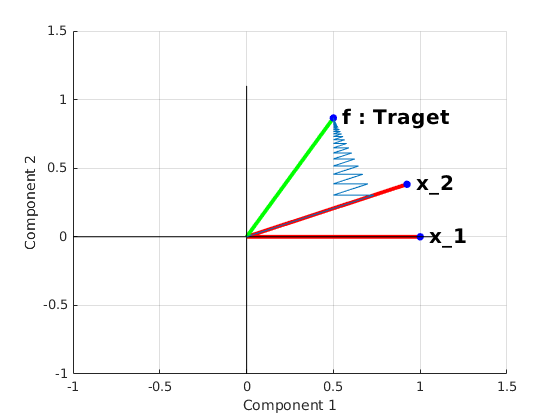

path = zeros(2,size(steps,2)+1);

h3 = plot(path(2,1),path(1,1));
xlim([-1,1.5]);ylim([-1,1.5]);
grid on
for i = 1: size(steps,2)
    path(:,i+1) = path(:,i)+steps(2,i)*D(:,steps(1,i));
    
    set(h3,'YData',path(2,1:i+1),'XData',path(1,1:i+1))
    pause(0.1)
end
hold off

It can be seen that even thouhg the algorithm achives convergence asymptotically. It takes large number of iterations for reduce the error. 

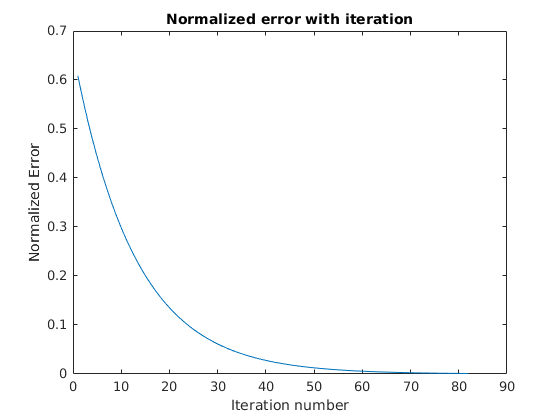

fig2 =figure("Name",'Normalized error with iteration');
plot(error_norm);
xlabel('Iteration number');
ylabel('Normalized Error');
title('Normalized error with iteration')

function [error_norm, f_k, R_k, steps] = MatchingPursuit(D, f,n_itr, epsilon)
% Iteratively approximte the target vector as a linear combination of
% vectors from a overcomplete dictionary.


error_norm = ones(1,n_itr);% Stores the normalized error in each iteration
steps = zeros(2,n_itr); % Stores the [direction_number ; length of direction] in each itr 

f_k = 0; % f0 : Initial position at origin
R_k = f; % R_kf : Initial residual is the traget

for k= 1:n_itr 
    
    ip = R_k.'*D;       % inner product
    
    [~, n]= max(abs(ip));   % maximum inner product
    
    f_k = f_k + ip(n)*D(:,n); % updating the approximation
    
    R_k = R_k - ip(n)*D(:,n); % updating the residual
    
    error_norm(k) = norm(f- f_k,2); % calculating error norm
    
    steps(:,k) = [n; ip(n)];
    
    % The stopping criteria can be chosen according to the application
    % Here it is chosen as normalized error tolerance
    if error_norm(k) <= epsilon 
        break
    end   
end

error_norm(k+1:end) = [];
steps(:,k+1:end)=[];
end